%Number of molecules.
num_of_mols = 10000;
%Distance between release point and reciever(Micrometers).
distance = 10;
transmitter_radius = 5;
transmitter_coordinates = [-transmitter_radius, 0, 0];
%Radius of the spherical reciever(Micrometers).
reciever_radius = 5;
reciever_coordinates = [distance, 0, 0];
%Diffusion coefficient(Micrometers^2/seconds).
coef = 79.4;
%Step size. (Seconds).
step = 10^-4;
%Total time. (Seconds).
time = 2;
%In micrometers per second

flow = [0, 0, 0];
%res = p2s(num_of_mols, reciever_radius, ...
%    reciever_coordinates, coef, step, time, flow);

%flow = [10, 0, 0];
%res = s2s_absorb(num_of_mols, reciever_radius, ...
%    reciever_coordinates, transmitter_radius ,transmitter_coordinates, ...
%    coef, step, time, flow);

%flow = [10, 0, 0];
%res = s2s_rollback(num_of_mols, reciever_radius, ...
%    reciever_coordinates, transmitter_radius ,transmitter_coordinates, ...
%    coef, step, time, flow);


xStart = 0;
dx = 0.01;
N = 200;
x = xStart + (0:N-1)*dx;

%Plot
h = hist(res,200);
number_of_hits = size(res);

ans =         3829           1


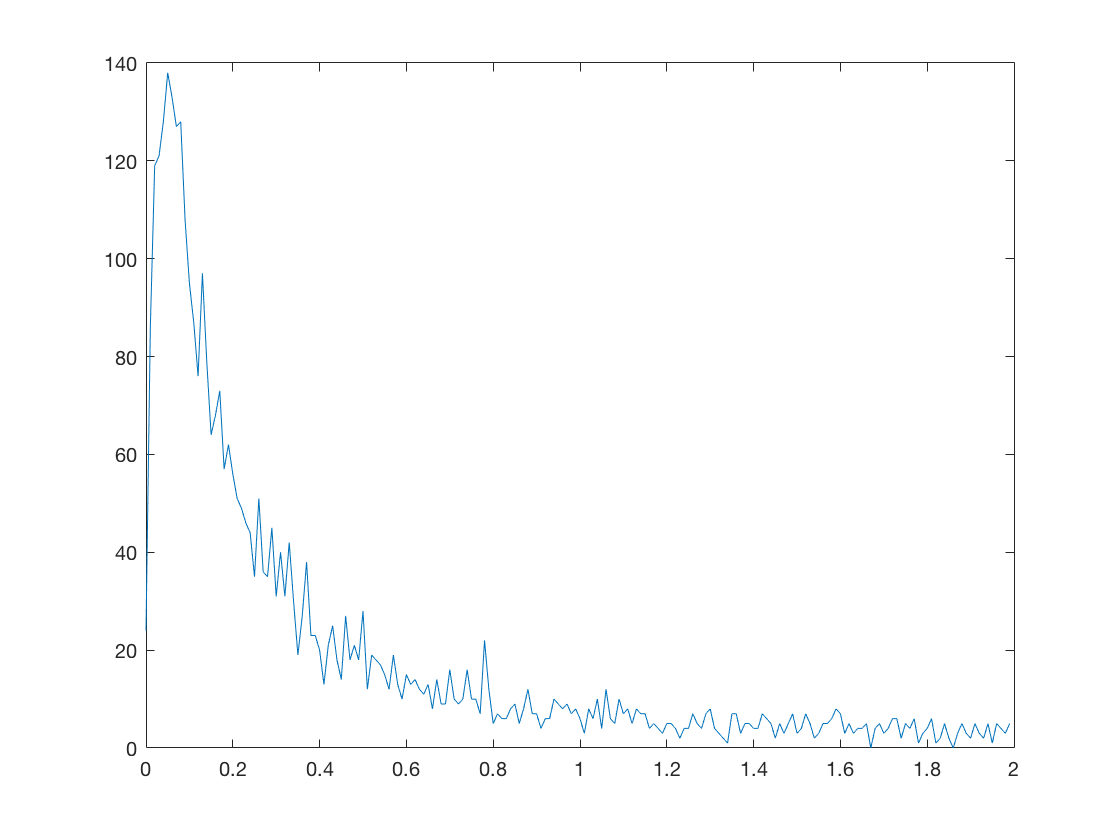

plot(x,h);

number_of_hits;


function arrival_times = p2s(num_of_mols, reciever_radius, reciever_coordinates, coef, step, time, flow)
%p2s Summary of this function goes here

%Molecule x, y, z coordinate matrix
mol_matrix = zeros(num_of_mols, 3); 
%Arrival times.
arrival_times = zeros(num_of_mols,1);
%Standart deviation of the gaussian diffusion motion.
std = sqrt(2 * coef * step);

%Simulation start.
for i = 1:time/step
    %Random movement vector generation.
    movements = normrnd(0,std, size(mol_matrix));

    %Molecule movementns added to positions.
    mol_matrix = mol_matrix + movements + (flow * step);
    
    mol_matrix_temp = mol_matrix;
    %Subtract each molecules position from sphere's coordinates.
    mol_matrix_temp = mol_matrix_temp - reciever_coordinates;
    %Square each value
    mol_matrix_temp = mol_matrix_temp.^2;
    %Sum of squares of values.
    sum_vector = sum(mol_matrix_temp, 2);
    %If Sum of squares is smaller or equal to radius^2, then it is a hit.
    hits = (sum_vector <= reciever_radius^2) & (arrival_times == 0);
    %Hits is a logical vector that holds 0 for no-hits, 1 for hits.
    %Store arrival times.
    arrival_times(hits) = i*step;

end

arrival_times = arrival_times(arrival_times ~= 0);

end

